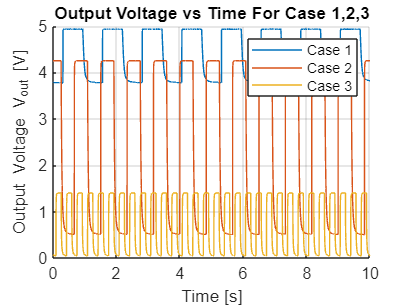

% Alperen Öztürk - 2575868 
% Muhammed Emin Özgün - 2575843
% Ömer Faruk Özmermer - 2516789 
samplingFrequency = 1960;
recordTime = length(c1)/samplingFrequency;
time = 0:1/samplingFrequency:recordTime;
time = time(1:end-1);

fftLength= length(c1);
freqs = samplingFrequency*(0:(fftLength/2))/fftLength;

%PART 1.1
figure(1);
hold on;
for caseNum = 1:3
    outputVoltage = eval(['c' num2str(caseNum)]);
    plot(time,outputVoltage);

end
hold off;
xlabel('Time [s]');
ylabel('Output Voltage V_{out} [V]');
grid on;
legend('Case 1', 'Case 2', 'Case 3');
title('Output Voltage vs Time For Case 1,2,3')

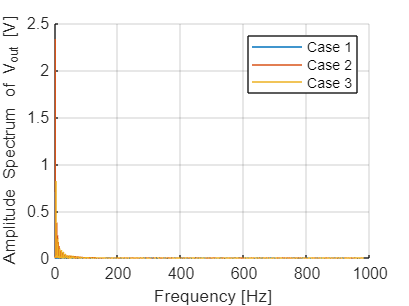

%PART 1.2




%PART 1.3
figure(2);
hold on;
for caseNum = 1:3
    outputVoltage = eval(['c' num2str(caseNum)]);
    FV=fft(outputVoltage-mean(outputVoltage));
    amplitudeSpectrum=abs(FV/fftLength);
    amplitudeSpectrum=amplitudeSpectrum(1:fftLength/2+1);
    amplitudeSpectrum(2:end-1) = 2*amplitudeSpectrum(2:end-1);
    semilogx(freqs, amplitudeSpectrum);
end
hold off;
xlabel('Frequency [Hz]');
ylabel('Amplitude Spectrum of V_{out} [V]');
grid on;
legend('Case 1', 'Case 2', 'Case 3')

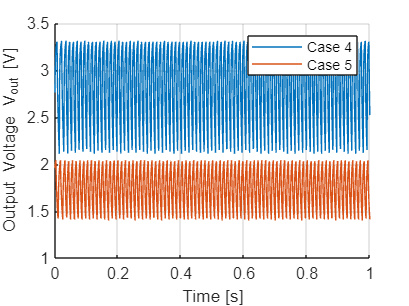



%PART 2.1
recordTime = length(c4)/samplingFrequency;
time = 0:1/samplingFrequency:recordTime;
time = time(1:end-1);
fftLength= length(c4);
freqs = samplingFrequency*(0:(fftLength/2))/fftLength;

figure(3);
hold on;
for caseNum = 4:5
    outputVoltage = eval(['c' num2str(caseNum)]);
    plot(time,outputVoltage);

end
hold off;
xlabel('Time [s]');
ylabel('Output Voltage V_{out} [V]');
grid on;
legend('Case 4', 'Case 5');


deltaV4 = max(c4)-min(c4)

deltaV4 = 1.2000

deltaV5 = max(c5) -min(c5)

deltaV5 = 0.6400

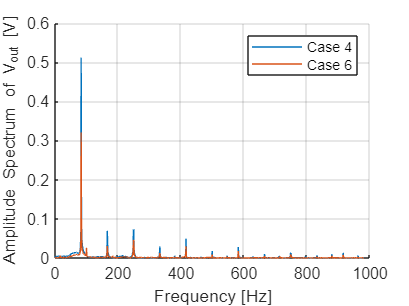

%PART 2.2
figure(4);
hold on;
for caseNum = 4:2:6
    outputVoltage = eval(['c' num2str(caseNum)]);
    FV=fft(outputVoltage-mean(outputVoltage));
    amplitudeSpectrum=abs(FV/fftLength);
    amplitudeSpectrum=amplitudeSpectrum(1:fftLength/2+1);
    amplitudeSpectrum(2:end-1) = 2*amplitudeSpectrum(2:end-1);
    semilogx(freqs, amplitudeSpectrum);
end
hold off;
xlabel('Frequency [Hz]');
ylabel('Amplitude Spectrum of V_{out} [V]');
grid on;
legend('Case 4', 'Case 6')

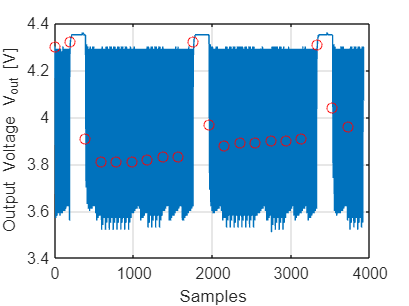



%PART 3

recordTime = length(msg)/samplingFrequency;
time = 0:1/samplingFrequency:recordTime;
time = time(1:end-1);
fftLength= length(msg);
freqs = samplingFrequency*(0:(fftLength/2))/fftLength;
samples=time*1960;
bitDuration = 0.1;
bitSamples = round(bitDuration * samplingFrequency);
numBits = 7;

figure(5)
plot(samples,msg);
xlabel('Samples')
ylabel('Output Voltage V_{out} [V]')
grid on
hold on;
startIndices = 1:bitSamples:length(msg);

for i = 1:length(startIndices)
    startIdx = startIndices(i) ;
    plot(samples(startIdx),msg(startIdx),'ro');
end

hold off;

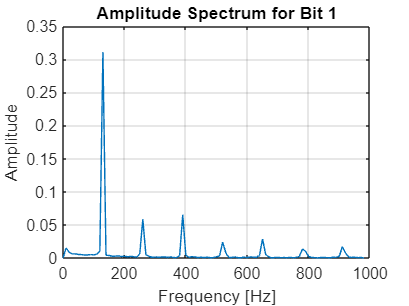

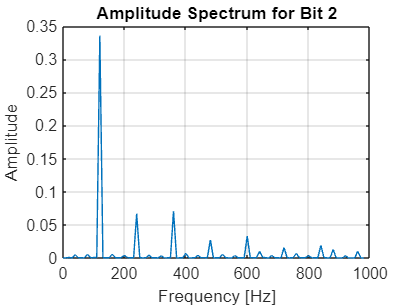

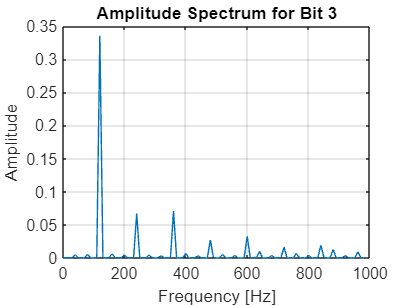

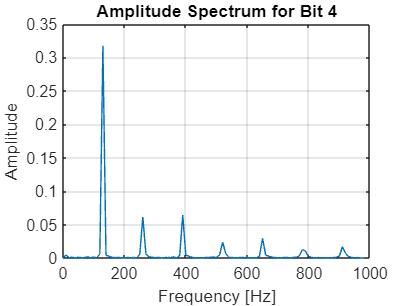

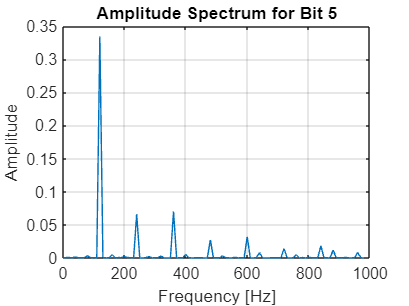

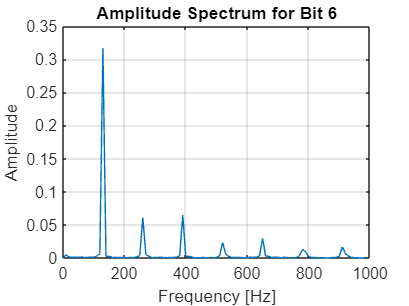

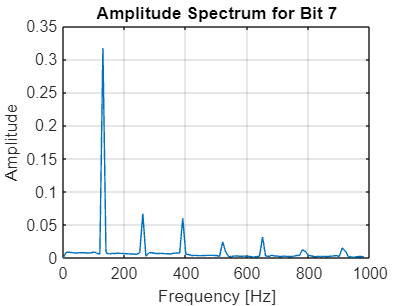



bitValues = cell(1,numBits);

figure(6)
for i = 1:numBits
    startIdx = startIndices(i+2);
    endIdx = startIdx + bitSamples - 1;
    bitSegment = msg(startIdx:endIdx);
    FV=fft(bitSegment - mean(bitSegment));
    amplitudeSpectrum = abs(FV/bitSamples);
    amplitudeSpectrum = amplitudeSpectrum(1:bitSamples/2+1);
    amplitudeSpectrum(2:end-1) = 2 * amplitudeSpectrum(2:end-1);

    freqs = samplingFrequency * (0:(bitSamples/2)) / bitSamples; % Update freqs
    % Create separate plots for bits 0 and 1
    figure;
    plot(freqs, amplitudeSpectrum);
    title(['Amplitude Spectrum for Bit ' num2str(i)]);
    xlabel('Frequency [Hz]');
    ylabel('Amplitude');
    grid on;
    
    [~, dominantIdx] = max(amplitudeSpectrum);
    dominantFrequency = freqs(dominantIdx);
    
    if dominantFrequency > 120
        bitValues{i} = '1';
    else
        bitValues{i} = '0';
    end
end


binaryMessage=strjoin(bitValues,"")

binaryMessage = '1001011'

decimalMessage = bin2dec(binaryMessage);
charMessage = char(decimalMessage);

% Display results
disp('Binary Message:');

Binary Message:


disp(binaryMessage);

1001011


disp('Decimal Message:');

Decimal Message:


disp(decimalMessage);

    75



disp('ASCII Message:');

ASCII Message:


disp(charMessage);

K
